# Comparing RGBW and RGB sensor noise

The neural networks are implemented in the demosaicing ONNX files. To run these, you must have the Python environment installed on your computer. See the instructions for installing Conda and connecting it to Matlab in

Or

Or

You must also have the ONNX files (ONNX) in the isethdrsensor/network. These can be downloaded using ieWebGet.

The ipCompute command to use these networks, for the RGBW case, is

The demosaic-denoise networks were trained on the ar0132at, both the 'rgbw' and 'rgb' sensor. The network runs for scenes with a reasonable illumination, but not well on the HDR scenes.

See also

## Initialize and make sure the ONNX files are present

ieInit;

fname = 'NNDemosaicRGB.onnx';
nFile = fullfile(isethdrsensorRootPath,'networks',fname);
if ~exist(nFile,"file")
    % Not found.  download the file from SDR
    ieWebGet('resourcetype','isethdrsensor',...
        'resource name',fullfile('networks',fname),...
        'download dir',isethdrsensorRootPath);
end

fname = 'NNDemosaicRGBW.onnx';
nFile = fullfile(isethdrsensorRootPath,'networks',fname);
if ~exist(nFile,"file")
    % Not found.  download the file from SDR
    ieWebGet('resourcetype','isethdrsensor',...
        'resource name',fullfile('networks',fname),...
        'download dir',isethdrsensorRootPath);
end

## Create the two sensors and IP

sensorRGBW = sensorCreate('ar0132at',[],'rgbw');
sensorRGB  = sensorCreate('ar0132at',[],'rgb');
sensorRGB  = sensorSet(sensorRGB,'exp time',1/60);
sensorRGBW = sensorSet(sensorRGBW,'exp time',1/60);

ipName = ipCreate;
ipName = ipSet(ipName,'demosaic method','Adaptive Laplacian');

## Color test scene

scene = sceneCreate('macbeth',80);

oi = oiCreate;
oi = oiCompute(oi, scene,'crop',true,'pixel size', 3e-6);

% Match the sensor spatial parameters to the OI
sensorRGB = sensorSet(sensorRGB,'match oi',oi);
sensorRGBW = sensorSet(sensorRGBW,'match oi',oi);

% We used this for the paper
% lux = [0.1: 0.1:1, 2:10];   % Zhenyi's original

% Here, we use a smaller number of levels.
lux = logspace(-2,1,3);

% Store the color accuracy.
dE_rgb= zeros(numel(lux),1);
dE_rgbNN= zeros(numel(lux),1);
dE_rgbwNN = zeros(numel(lux),1);

% To make a montage of the images
rgbImg = cell(numel(lux),1);
rgbNNImg = cell(numel(lux),1);
rgbwNNImg = cell(numel(lux),1);

## Start low, and progress to high, optical image illuminance

for ii = 1:numel(lux)
    oi = oiAdjustIlluminance(oi, lux(ii));
    
    % rgb
    thisSensorRGB = sensorCompute(sensorRGB,oi);
    ipRGB = ipCompute(ipName, thisSensorRGB);
    rgbImg{ii} = ipGet(ipRGB, 'srgb');

    % rgbw using restormer
    ipRGBNN = ipCompute(ipName,thisSensorRGB,'network demosaic','ar0132at-rgb');
    rgbNNImg{ii} = ipGet(ipRGBNN, 'srgb');

    % rgbw using restormer
    thisSensorRGBW = sensorCompute(sensorRGBW,oi);
    ipRGBWNN = ipCompute(ipName,thisSensorRGBW,'network demosaic','ar0132at-rgbw');
    rgbwNNImg{ii} = ipGet(ipRGBWNN, 'srgb');

    if ii==1
        % Make the ground truth image data the first time
        sensorI = sensorCreateIdeal('match',sensorRGB);
        sensorI = sensorCompute(sensorI,oi);
        % sensorWindow(sensorI(3));
        gtImg(:,:,1) = sensorI(1).data.volts;
        gtImg(:,:,2) = sensorI(2).data.volts;
        gtImg(:,:,3) = sensorI(3).data.volts;

        ipIdeal = ipRGB;
        ipIdeal = ipSet(ipIdeal, 'demosaic method', 'skip');
        ipIdeal = ipSet(ipIdeal, 'transform method', 'current');
        % Set the sensor space image in the image processing structure
        ipIdeal = ipSet(ipIdeal, 'sensor space', gtImg);

        % Compute the final image processing
        ipIdeal = ipCompute(ipIdeal, thisSensorRGB);

        % ipWindow(ipIdeal);
        rgbGT = ipGet(ipIdeal, 'srgb');
        rgbGT = ieScale(rgbGT, 1);
    end

    rgbImg{ii}    = ieScale(rgbImg{ii}, 1);
    rgbNNImg{ii}  = ieScale(rgbNNImg{ii}, 1);
    rgbwNNImg{ii} = ieScale(rgbwNNImg{ii}, 1);
    
    dE_rgb(ii)    = mean2(imcolordiff(rgbGT, rgbImg{ii}));
    dE_rgbNN(ii)  = mean2(imcolordiff(rgbGT, rgbNNImg{ii}));
    dE_rgbwNN(ii) = mean2(imcolordiff(rgbGT, rgbwNNImg{ii}));
end

INFO: Input image is RGB
INFO: Demosaicing is successfully completed.


INFO: Input image is RGBW
INFO: Demosaicing is successfully completed.
INFO: Input image is RGB
INFO: Demosaicing is successfully completed.
INFO: Input image is RGBW

INFO: Demosaicing is successfully completed.
INFO: Input image is RGB
INFO: Demosaicing is successfully completed.
INFO: Input image is RGBW
INFO: Demosaicing is successfully completed.


## Show the reconstructed images side by side

The RGBW performance is (somewhat) better than RGB.  

Look in detail at the noise in the gray matches, particularly the darker ones, in the middle rendering where the RGB is on the left and rhte RGBW is on the right.  This is not life-changing stuff, but the W does help in the noise on the darker patches in the middle and it helps with most of the patches at the top.  It gives up nothing for the brightest rendering, at the bottom.

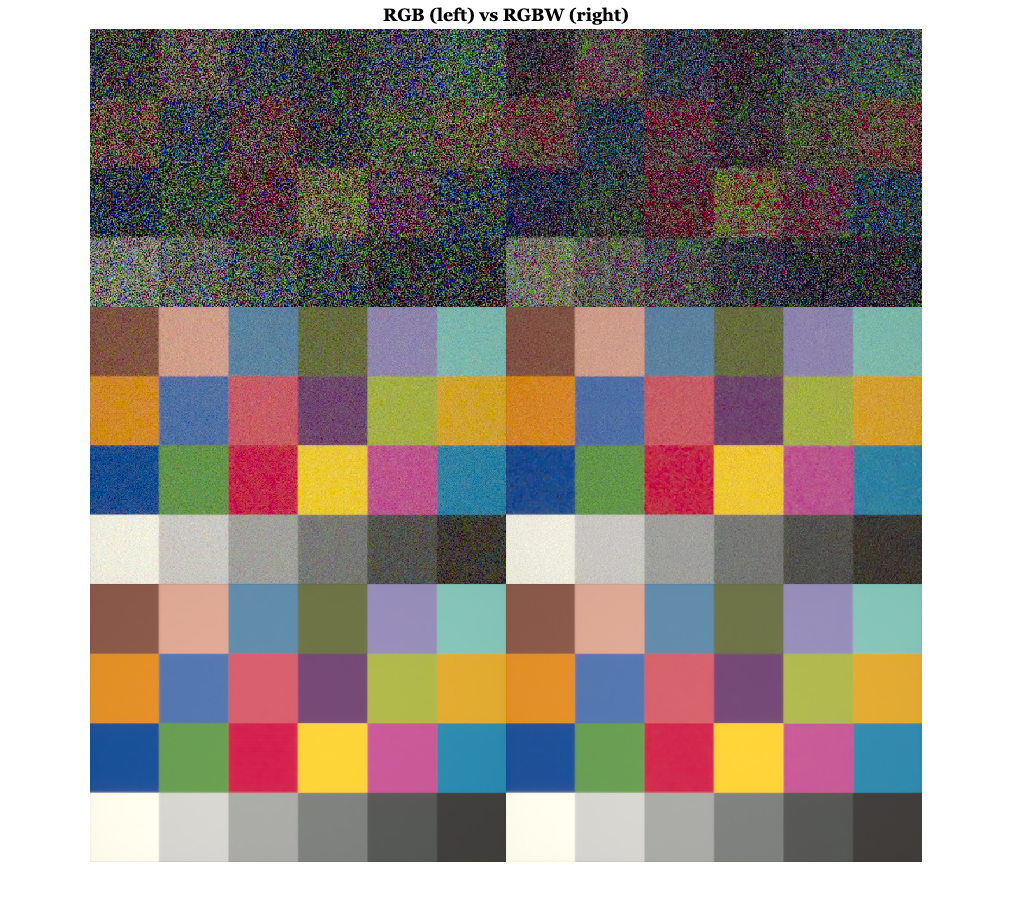

imgCompare = cell(numel(lux)*2,1);
for ii=1:numel(lux)
    imgCompare{1 + 2*(ii-1)} = rgbNNImg{ii};
    imgCompare{2 + 2*(ii-1)} = rgbwNNImg{ii};
end

ieNewGraphWin; montage(imgCompare,'size',[numel(lux),2]); 
title('RGB (left) vs RGBW (right)')

## Plot the $\Delta$E error metrics

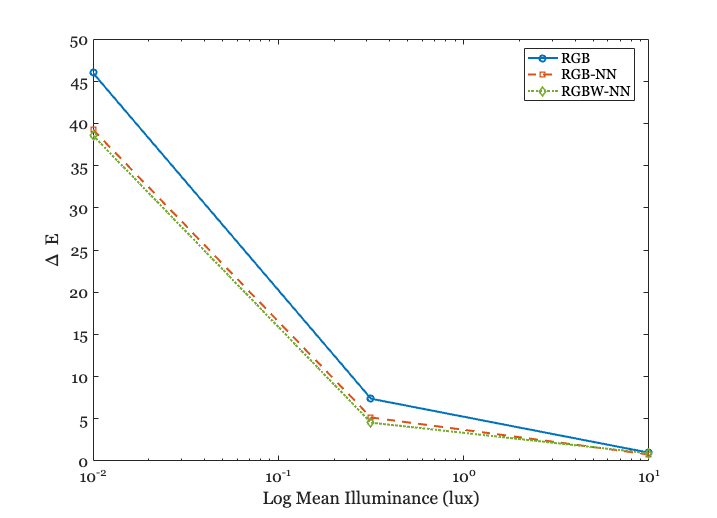

ieNewGraphWin;

plot(lux, dE_rgb(:), 'color', [0.0000, 0.4470, 0.7410], 'LineWidth', 2, 'LineStyle', '-', 'Marker', 'o', 'MarkerSize', 6); hold on  
plot(lux, dE_rgbNN(:), 'color', [0.8500, 0.3250, 0.0980], 'LineWidth', 2, 'LineStyle', '--', 'Marker', 's', 'MarkerSize', 6);         
plot(lux, dE_rgbwNN(:), 'color', [0.4660, 0.6740, 0.1880], 'LineWidth', 2, 'LineStyle', ':', 'Marker', 'd', 'MarkerSize', 6);       

legend('RGB', 'RGB-NN', 'RGBW-NN', 'FontSize', 14, 'Location', 'Best');
xlabel('Log Mean Illuminance (lux)', 'FontSize', 16);
ylabel('\Delta E', 'FontSize', 16);
set(gca, 'FontSize', 16);
set(gca, 'XScale', 'log');

## Reset the variables for the FruitCC analysis 

This is another way to see the noise improvement, using a real image.

ieInit;
initClear = ieSessionGet('init clear');
ieSessionSet('init clear',true);

% Make sure we have the FruitMCC locally
filename = 'FruitMCC.mat';
filePath = which(filename);
if isempty(filePath)
    filePath =ieWebGet('resourcetype','isethdrsensor',...
        'resource name','data/FruitMCC.mat',...
        'download dir',fullfile(isethdrsensorRootPath));
end

% Read the FruitMCC and convert to OI.
scene = sceneFromFile(filePath,'multispectral',[],[],400:10:700);

Reading multispectral data with mcCOEF.
Saved using principal component method


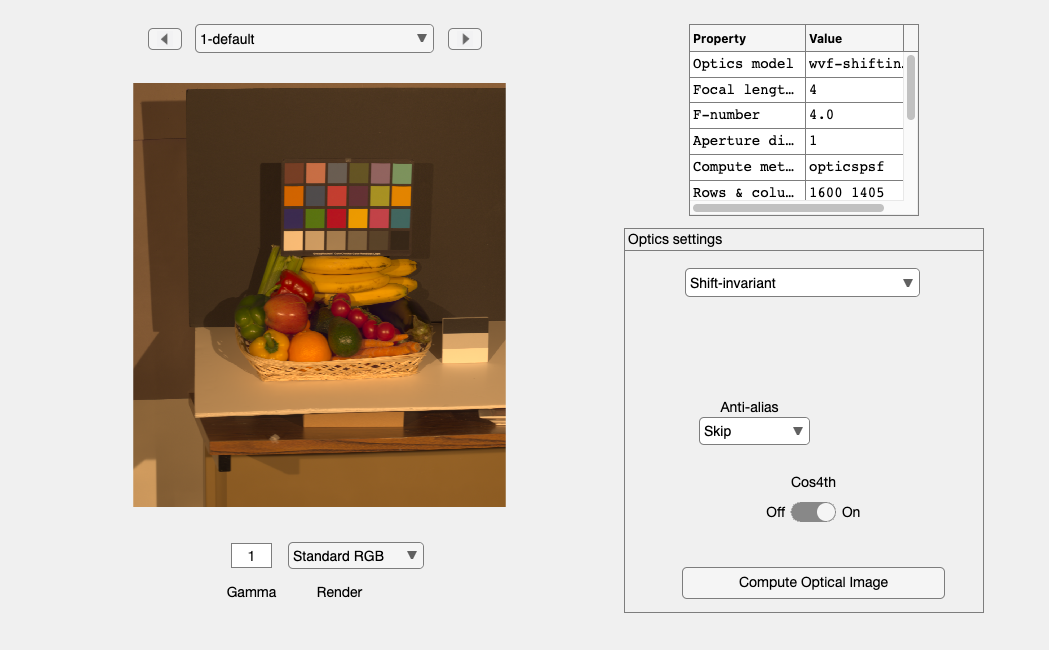

oi = piOICreate(sceneGet(scene,'photons'));
oiWindow(oi); drawnow;

## Loop through two light levels and compute rendered image

sensorRGBW = sensorCreate('ar0132at',[],'rgbw');
sensorRGB  = sensorCreate('ar0132at',[],'rgb');
sensorRGB  = sensorSet(sensorRGB,'exp time',1/60);
sensorRGBW = sensorSet(sensorRGBW,'exp time',1/60);

sensorRGB  = sensorSet(sensorRGB,'pixel size constant fill factor',4e-6);
sensorRGB  = sensorSet(sensorRGB, 'sensor size', [512, 512]);
sensorRGBW = sensorSet(sensorRGBW,'pixel size constant fill factor',4e-6);
sensorRGBW = sensorSet(sensorRGBW, 'sensor size', [512, 512]);

ip = ipCreate;
ip = ipSet(ip,'demosaic method','Adaptive Laplacian'); 

lux = [0.1, 0.25];
ipRGB   = cell(numel(lux),1);
ipRGBNN = cell(numel(lux),1);
ipRGBWNN= cell(numel(lux),1);

rgbImg = cell(numel(lux),1);
rgbNNImg = cell(numel(lux),1);
rgbwNNImg = cell(numel(lux),1);

ssim_rgb    = zeros(numel(lux),1);
ssim_rgbNN  = zeros(numel(lux),1);
ssim_rgbwNN = zeros(numel(lux),1);

## Compute the RGB images for comparison

INFO: Demosaicing started ...


INFO: Input image is RGB
INFO: Demosaicing is successfully completed.


Elapsed time for ipComputeNN function: 8.43 seconds


INFO: Demosaicing started ...


INFO: Input image is RGBW
INFO: Demosaicing is successfully completed.


Elapsed time for ipComputeNN function: 12.16 seconds


INFO: Demosaicing started ...


INFO: Input image is RGB
INFO: Demosaicing is successfully completed.


Elapsed time for ipComputeNN function: 8.35 seconds


INFO: Demosaicing started ...


INFO: Input image is RGBW
INFO: Demosaicing is successfully completed.


Elapsed time for ipComputeNN function: 12.32 seconds


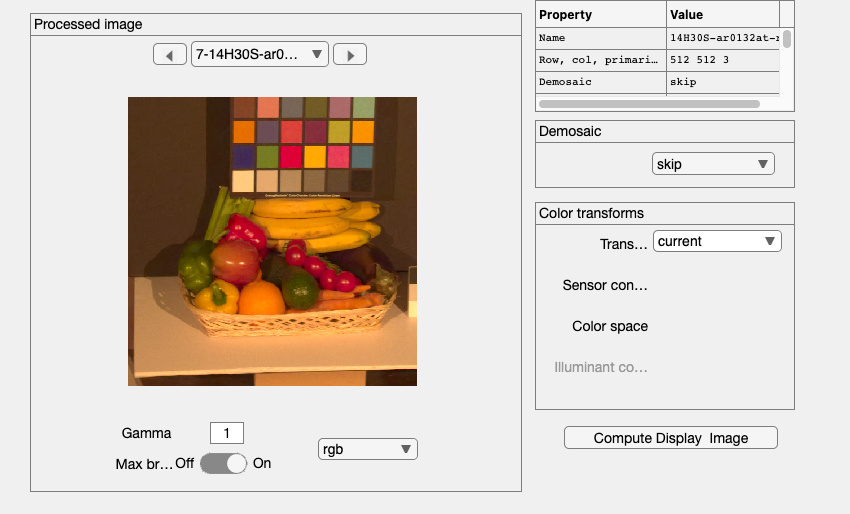

% Loop over lux levels
for ii = 1:numel(lux)
    oi = oiAdjustIlluminance(oi, lux(ii));

    % Standard rgb processing
    thisSensorRGB = sensorCompute(sensorRGB,oi);
    ipRGB{ii} = ipCompute(ip, thisSensorRGB);
    ipWindow(ipRGB{ii}); 
    rgbImg{ii} = ipGet(ipRGB{ii}, 'srgb');

    % rgb using restormer
    ipRGBNN{ii} = ipCompute(ip,thisSensorRGB, 'network demosaic','ar0132at-rgb');
    ipWindow(ipRGBNN{ii});
    rgbNNImg{ii} = ipGet(ipRGBNN{ii}, 'srgb');
    
    % rgbw using restormer
    thisSensorRGBW = sensorCompute(sensorRGBW,oi);
    ipRGBWNN{ii} = ipCompute(ip,thisSensorRGBW, 'network demosaic','ar0132at-rgbw');
    ipWindow(ipRGBWNN{ii}); 
    rgbwNNImg{ii} = ipGet(ipRGBWNN{ii}, 'srgb');

    % Get the ground truth (no noise)
    if ii==1
        % Make the ground truth image data the first time
        sensorI = sensorCreateIdeal('match',sensorRGB);
        sensorI = sensorCompute(sensorI,oi);
        % sensorWindow(sensorI(3));
        gtImg(:,:,1) = sensorI(1).data.volts;
        gtImg(:,:,2) = sensorI(2).data.volts;
        gtImg(:,:,3) = sensorI(3).data.volts;

        ipIdeal = ipRGB{1};
        ipIdeal = ipSet(ipIdeal, 'demosaic method', 'skip');
        ipIdeal = ipSet(ipIdeal, 'transform method', 'current');

        % Set the sensor space image in the image processing structure
        ipIdeal = ipSet(ipIdeal, 'sensor space', gtImg);

        % Compute the final image processing
        ipIdeal = ipCompute(ipIdeal, thisSensorRGB);

        ipWindow(ipIdeal); 
        drawnow;
        rgbGT = ipGet(ipIdeal, 'srgb');
        rgbGT = ieScale(rgbGT, 1);
    end
    
    rgbImg{ii}    = ieScale(rgbImg{ii}, 1);
    rgbNNImg{ii}  = ieScale(rgbNNImg{ii}, 1);
    rgbwNNImg{ii} = ieScale(rgbwNNImg{ii}, 1);
    
    % SSIM metric
    ssim_rgb(ii)    = ssim(rgbImg{ii}, rgbGT);
    ssim_rgbNN(ii)  = ssim(rgbNNImg{ii}, rgbGT);
    ssim_rgbwNN(ii) = ssim(rgbwNNImg{ii}, rgbGT);
end


% Save for later
ipName = {'ipRGB','ipRGBNN','ipRGBWNN'};
ipList{1} = ipRGB;
ipList{2} = ipRGBNN;
ipList{3} = ipRGBWNN;

## Show the relative noise of the RGB and RGBW

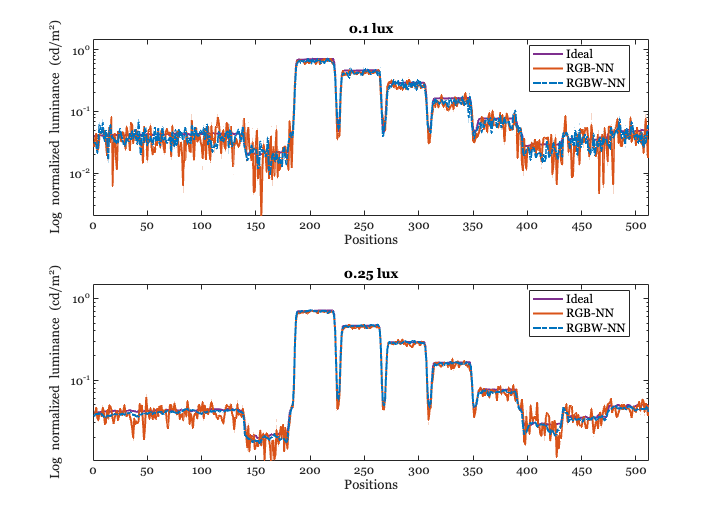

ieNewGraphWin;
whichLine = 155;

% Define colors and line styles for better distinction
colors = {[0.4660, 0.6740, 0.1880],[0.8500, 0.3250, 0.0980],  [0.0000, 0.4470, 0.7410]};
lineStyles = {'-', '-', '-.'};
titleNames = {'0.1 lux', '0.25 lux'};
for nn = 1:2
    subplot(2, 1, nn);
    % Plot for ipIdeal
    data = ipGet(ipIdeal, 'data luminance');
    data = ieScale(data, 1);
    plot(data(whichLine,:,1), 'color', [0.4940, 0.1840, 0.5560], 'LineWidth', 2, 'LineStyle', '-'); hold on  
    
    % Plot for ipRGB
    for ss = 2:3
        thisIP = ipList{ss};
        data = ipGet(thisIP{nn}, 'data luminance');
        data = ieScale(data, 1);
        % data = ipGet(thisSensor{nn}, 'data display');data = data(:,:,2);
        plot(data(whichLine,:,1), 'color', colors{ss}, 'LineWidth', 2, 'LineStyle', lineStyles{ss}); 
    end

    % Customize each subplot
    legend('Ideal', 'RGB-NN', 'RGBW-NN', 'FontSize', 12, 'Location', 'Best');
    xlabel('Positions', 'FontSize', 14);
    ylabel('Log normalized luminance (cd/m^2)', 'FontSize', 12);
    set(gca, 'FontSize', 12);
    xlim([0, 512]);
    ylim([0, 1.5]);
    title(titleNames{nn})
    set(gca, 'YScale', 'log');
end